# Swath profiles

Swath profiles are a good way to get an overview of the topography in a given setting and TopoToolbox has some easy ways to do this.

In this practical you will learn how to generate Swath profiles interactively from TopoToolbox and interpret them in the context of tectonics and geology.

First lets clear the workspace, command window and close all figures and load the DEM.

clear
clc
close all
 
DEM = GRIDobj('../data/BW_DEM.tif'); % load DEM
DEM.Z(end,:)= 2000;                  % condition DEM that streams don't flow south

The location of swath profiles is chosen interactively. But you will need to set a certain width for the swath, say 10 km (our map units are in meters!). When the map opens, single click to start the swath and click to add different line edges; double click to end the swath line.

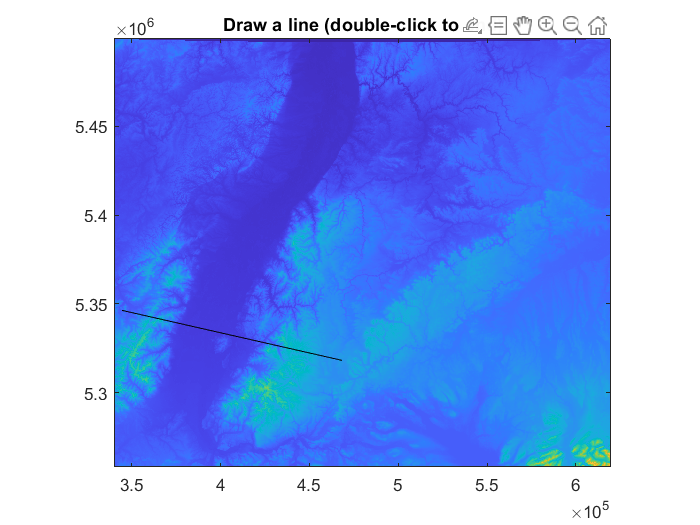

SW = SWATHobj(DEM,'width',10000);

Note that you can also specify a bunch of other parameters for the SWATHobj just type "help SWATHobj for more information. Also remember that you can see what type of methods (e.g. functions) are associated with the SWATHobj data class by typing "methods SWATHobj. Look at what your swath object contains.  

Note that it contains info about the coordinate endpoints you clicked (xy0), the width of the swath, and the swath values (Z).

SW

SW =   SWATHobj with properties:

       xy0: [2×2 double]
       zd0: [2×2 single]
        dx: 90
        dy: 90
     width: 5000
       gap: 0
    smooth: []
        xy: [1412×2 double]
     distx: [1412×1 double]
     disty: [56×1 double]
         X: [56×1412 double]
         Y: [56×1412 double]
         Z: [56×1412 double]
      name: 'SWATHobj created from GRIDobj BW_DEM'
    xyunit: []
     zunit: []
    georef: [1×1 struct]


Use the 'plot' command to show the swath in map view. In this case, 'plot' is a TopoToolbox SWATHobj method rather than the common Matlab function. 

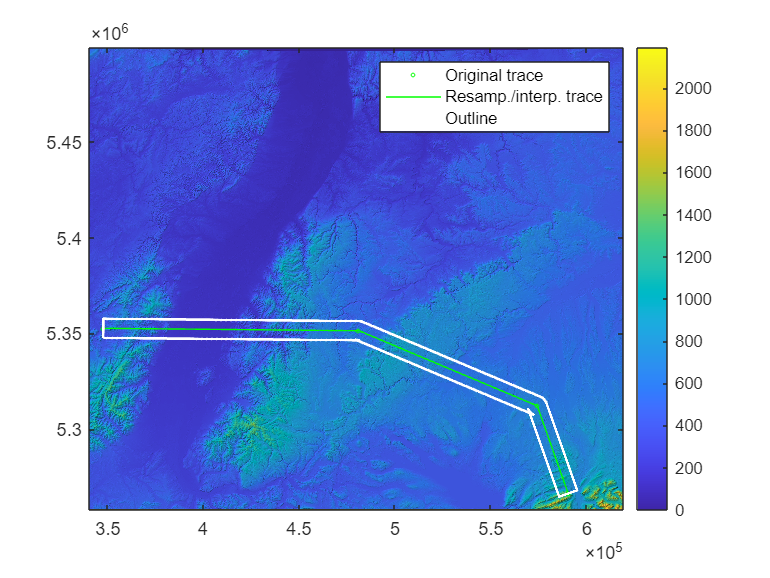

figure()
imageschs(DEM);
hold on
plot(SW)    

Now let’s plot your swath elevation data. Typically swaths are plotted with the mean elevation and either maximum and minimum elevations or the standard deviation of the elevation. Use the 'plotdz' function to show the data along your profile.

figure()
plotdz(SW)

The x-axis of swath profiles does not automatically detect the unit. If you want the axis to read meters, you need to adjust this by hand.

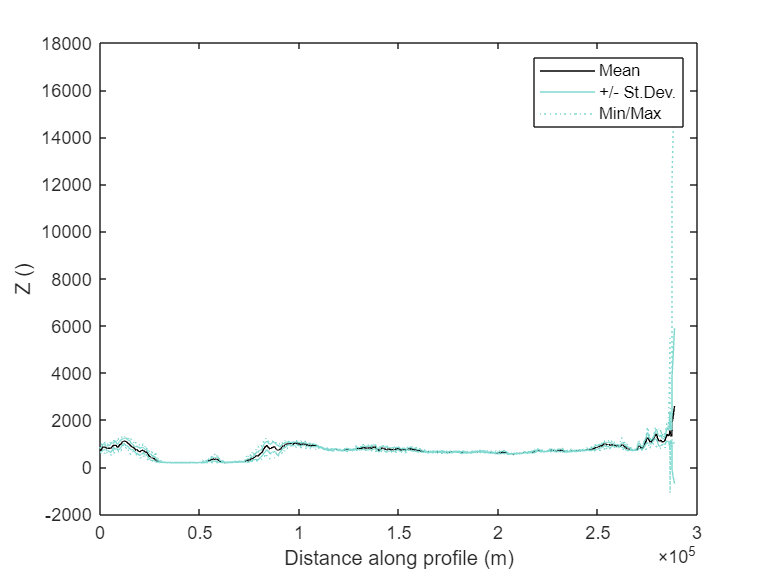

xlabel('Distance along profile (m)')

### Save the figure

Save the swath profile subplot figure you just made. You can do this by selecting save in the figure GUI or you can save it as follows (note: you may want to change the output file type).

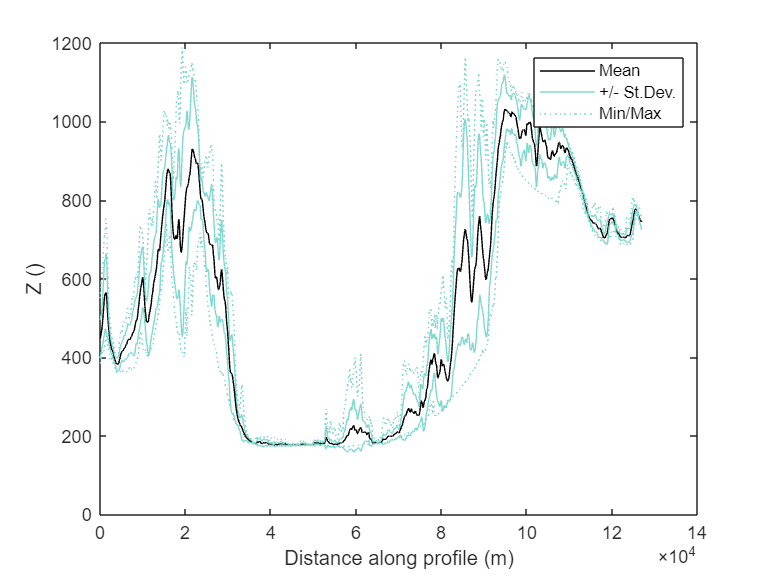

exportgraphics(gcf,'BW_swath1.png');  % saves as a png file

You can also save your SWATHobj as a shapefile that can be added to a GIS project. We will save only the lines from the SWATHobj, but you can also save the individual points if you wish.

MSl = SWATHobj2gds(SW,'lines');                % write map strcuture
shapewrite(MSl,'BW_swath1_lines.shp');         % export map structure

You can also extract data from rasters other than DEMs alog the same swath. Let's make a local relief map with 1000m radius and extract relief along the swath.

locrel = localtopography(DEM,1000);

extract the local relief data along the swath profile from before

SWlocrel = mapswath(SW,locrel);

Make a swath profile plot of your local relief along the swath profile. This plot is the same as the elevation swath before, just with local relief values instead.

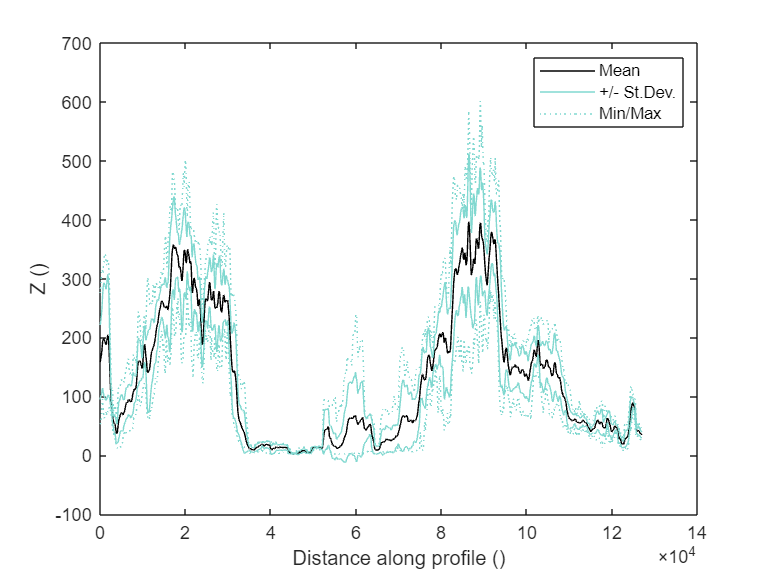

figure()
plotdz(SWlocrel)

Experiment with swaths in southwestern Germany. Take swaths, plot them with 'plodtdz'. Try to put your swath profiles perpendicular to large structures and geologic contacts because that will maximize your chance of seeing differences. Also, run a swath along a geologic structure to see along-strike variations. For instance, run one swath profile along the crest of the high topography on the east side of the Upper Rhine Graben parallel to the structure and check for along-strike changes in topography.

For better orientation always plot your swath mapview and profile next to eachother in a 1by2 plot.

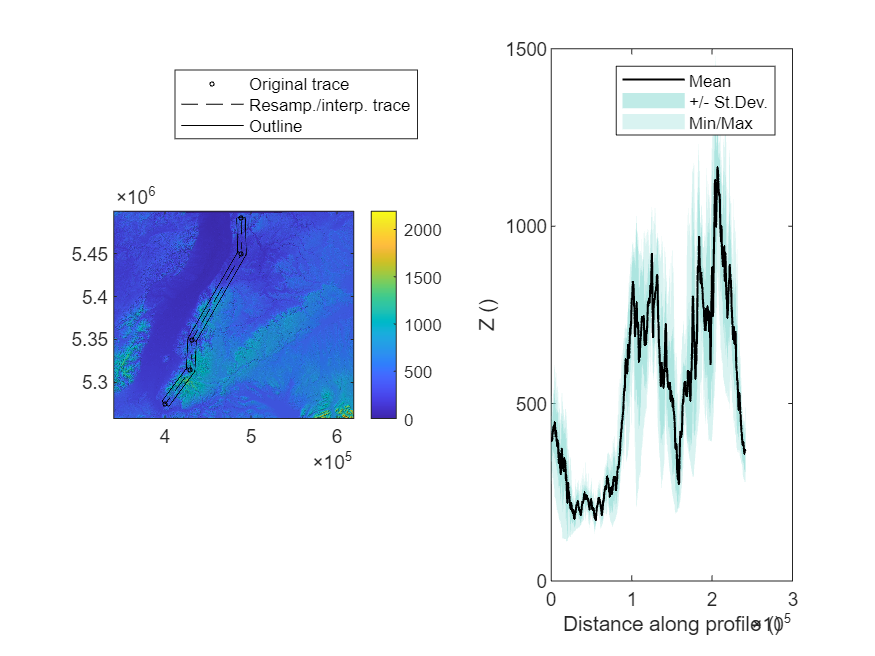

SW = SWATHobj(DEM,'width',10000);

figure()
tiledlayout(1,2)
nexttile
imageschs(DEM,[])
hold on
plot(SW)
nexttile
plotdz(SW)

Choose three swath profiles that tell you the most about elevation and relief variations among the different regions we've defined in practical P1. You could for instance do one along the crest of the Rhine Graben and then 2 more than are more oriented perpendicular to major structures (Rhine Graben or Swabian Alb). Swath profiles also don't need to be entirely straight! The middle line can contain many segments, just click piece by piece.

SW1 = SWATHobj(DEM,'width',10000);
SW2 = SWATHobj(DEM,'width',10000);
SW3 = SWATHobj(DEM,'width',10000);

Calculate local relief along those swatch profiles

SWlocrel1 = mapswath(SW1,locrel);
SWlocrel2 = mapswath(SW2,locrel);
SWlocrel3 = mapswath(SW3,locrel);

Create a 3-by-3 plot  with the map view of the swaths on the left side (choose whether you prefer elevation or local relief as a basemap), the elevation swaths in the middle, and the local relief swaths on the right. Add titles and labels for orientation. 

Define topographic characteristics for the different regions, we've defined earlier. Write down explicitly things like: region X: high elevation, low relief, elevation lowering to south.

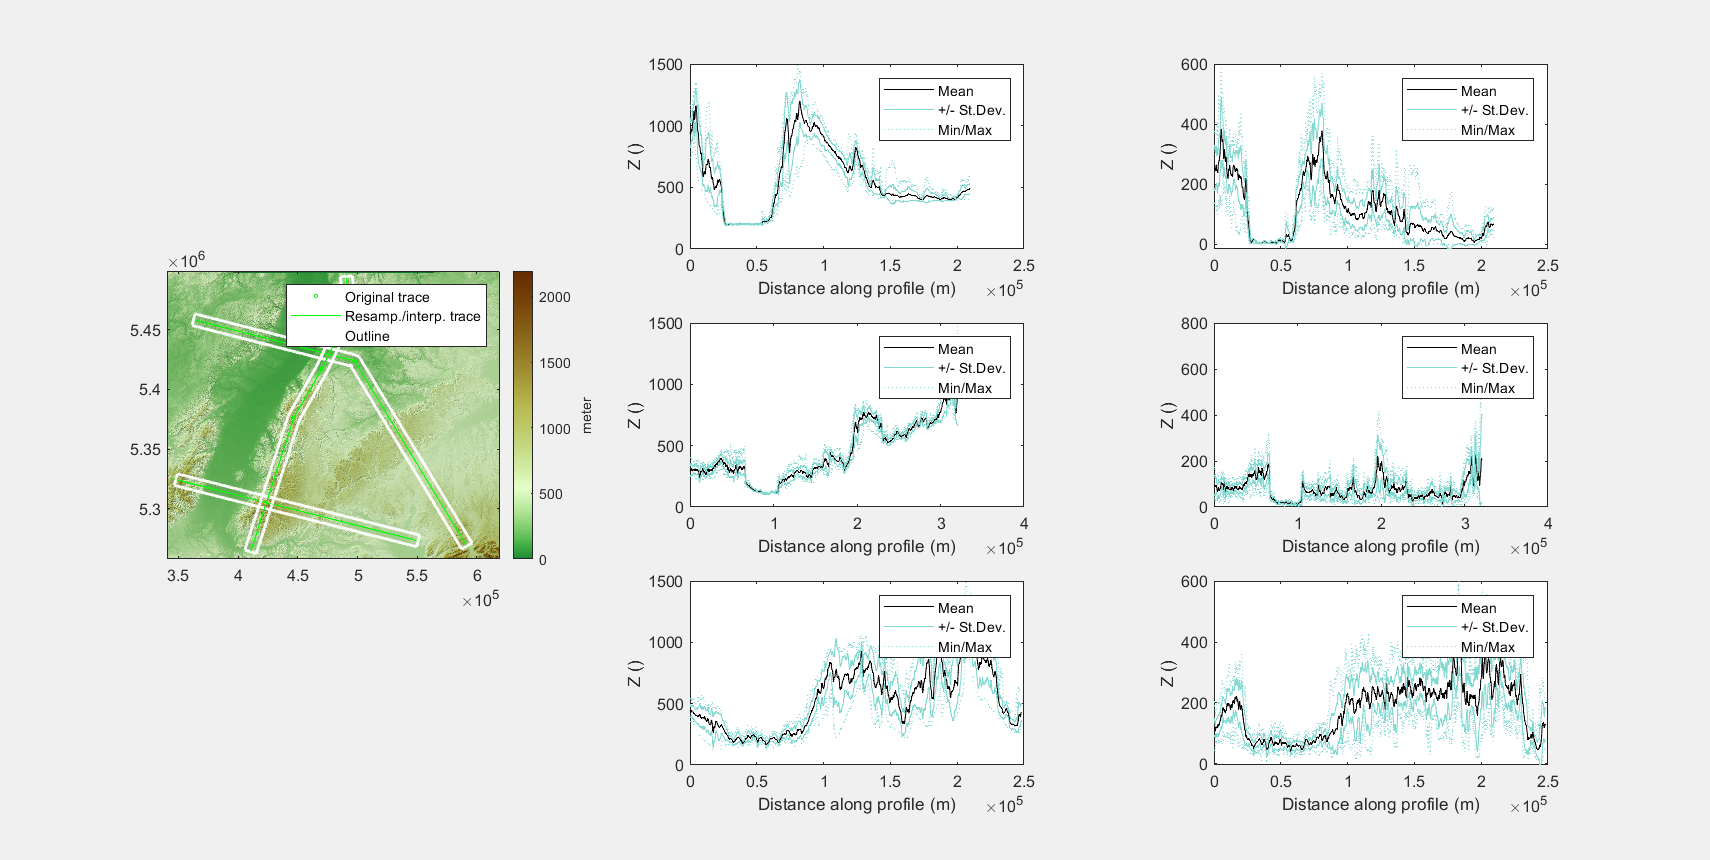

figure()
set(gcf,'Visible','on', 'units','normalized','outerposition',[0.05 0.05 0.90 0.90]) % this just makes sure the plot appears in a new large window for better visibility
tiledlayout(3,3)

% plot DEM and swath traces
ax1 = nexttile(1, [3, 1]); % [3, 1] means 3 rows and 1 column
axes(ax1);
imageschs(DEM,[],'colormap',landcolor,'colorbarylabel','meter');
hold on
plot(SW1)   
plot(SW2)
plot(SW3)

% plot swath 1
nexttile(2)
plotdz(SW1)   % elevation swath
xlabel('Distance along profile (m)')
% plot local relief swath 1
nexttile(3) 
plotdz(SWlocrel1) % elevation swath
xlabel('Distance along profile (m)')

% swath 2
nexttile(5)
plotdz(SW2) % elevation swath
xlabel('Distance along profile (m)')
nexttile(6)
plotdz(SWlocrel2) 
xlabel('Distance along profile (m)')
% swath 3
nexttile(8)
plotdz(SW3) % elevation swath
xlabel('Distance along profile (m)')
nexttile(9)
plotdz(SWlocrel3) 
xlabel('Distance along profile (m)')

If you want a small challenge, try to write code that changes the line color and line width for this figure.

### Swabian Alb

The relief characteristics of the Swabian Alb are particularly interesting. Run one swath profile along the strike of the Swabian Alb neart its crest (northwestern side) and run a wide (maybe something like 50 km) swath profile perpendicular to the strike across the mountain range. And then analyze. Does higher elevation lead to higher relief or is there a disconnect? 

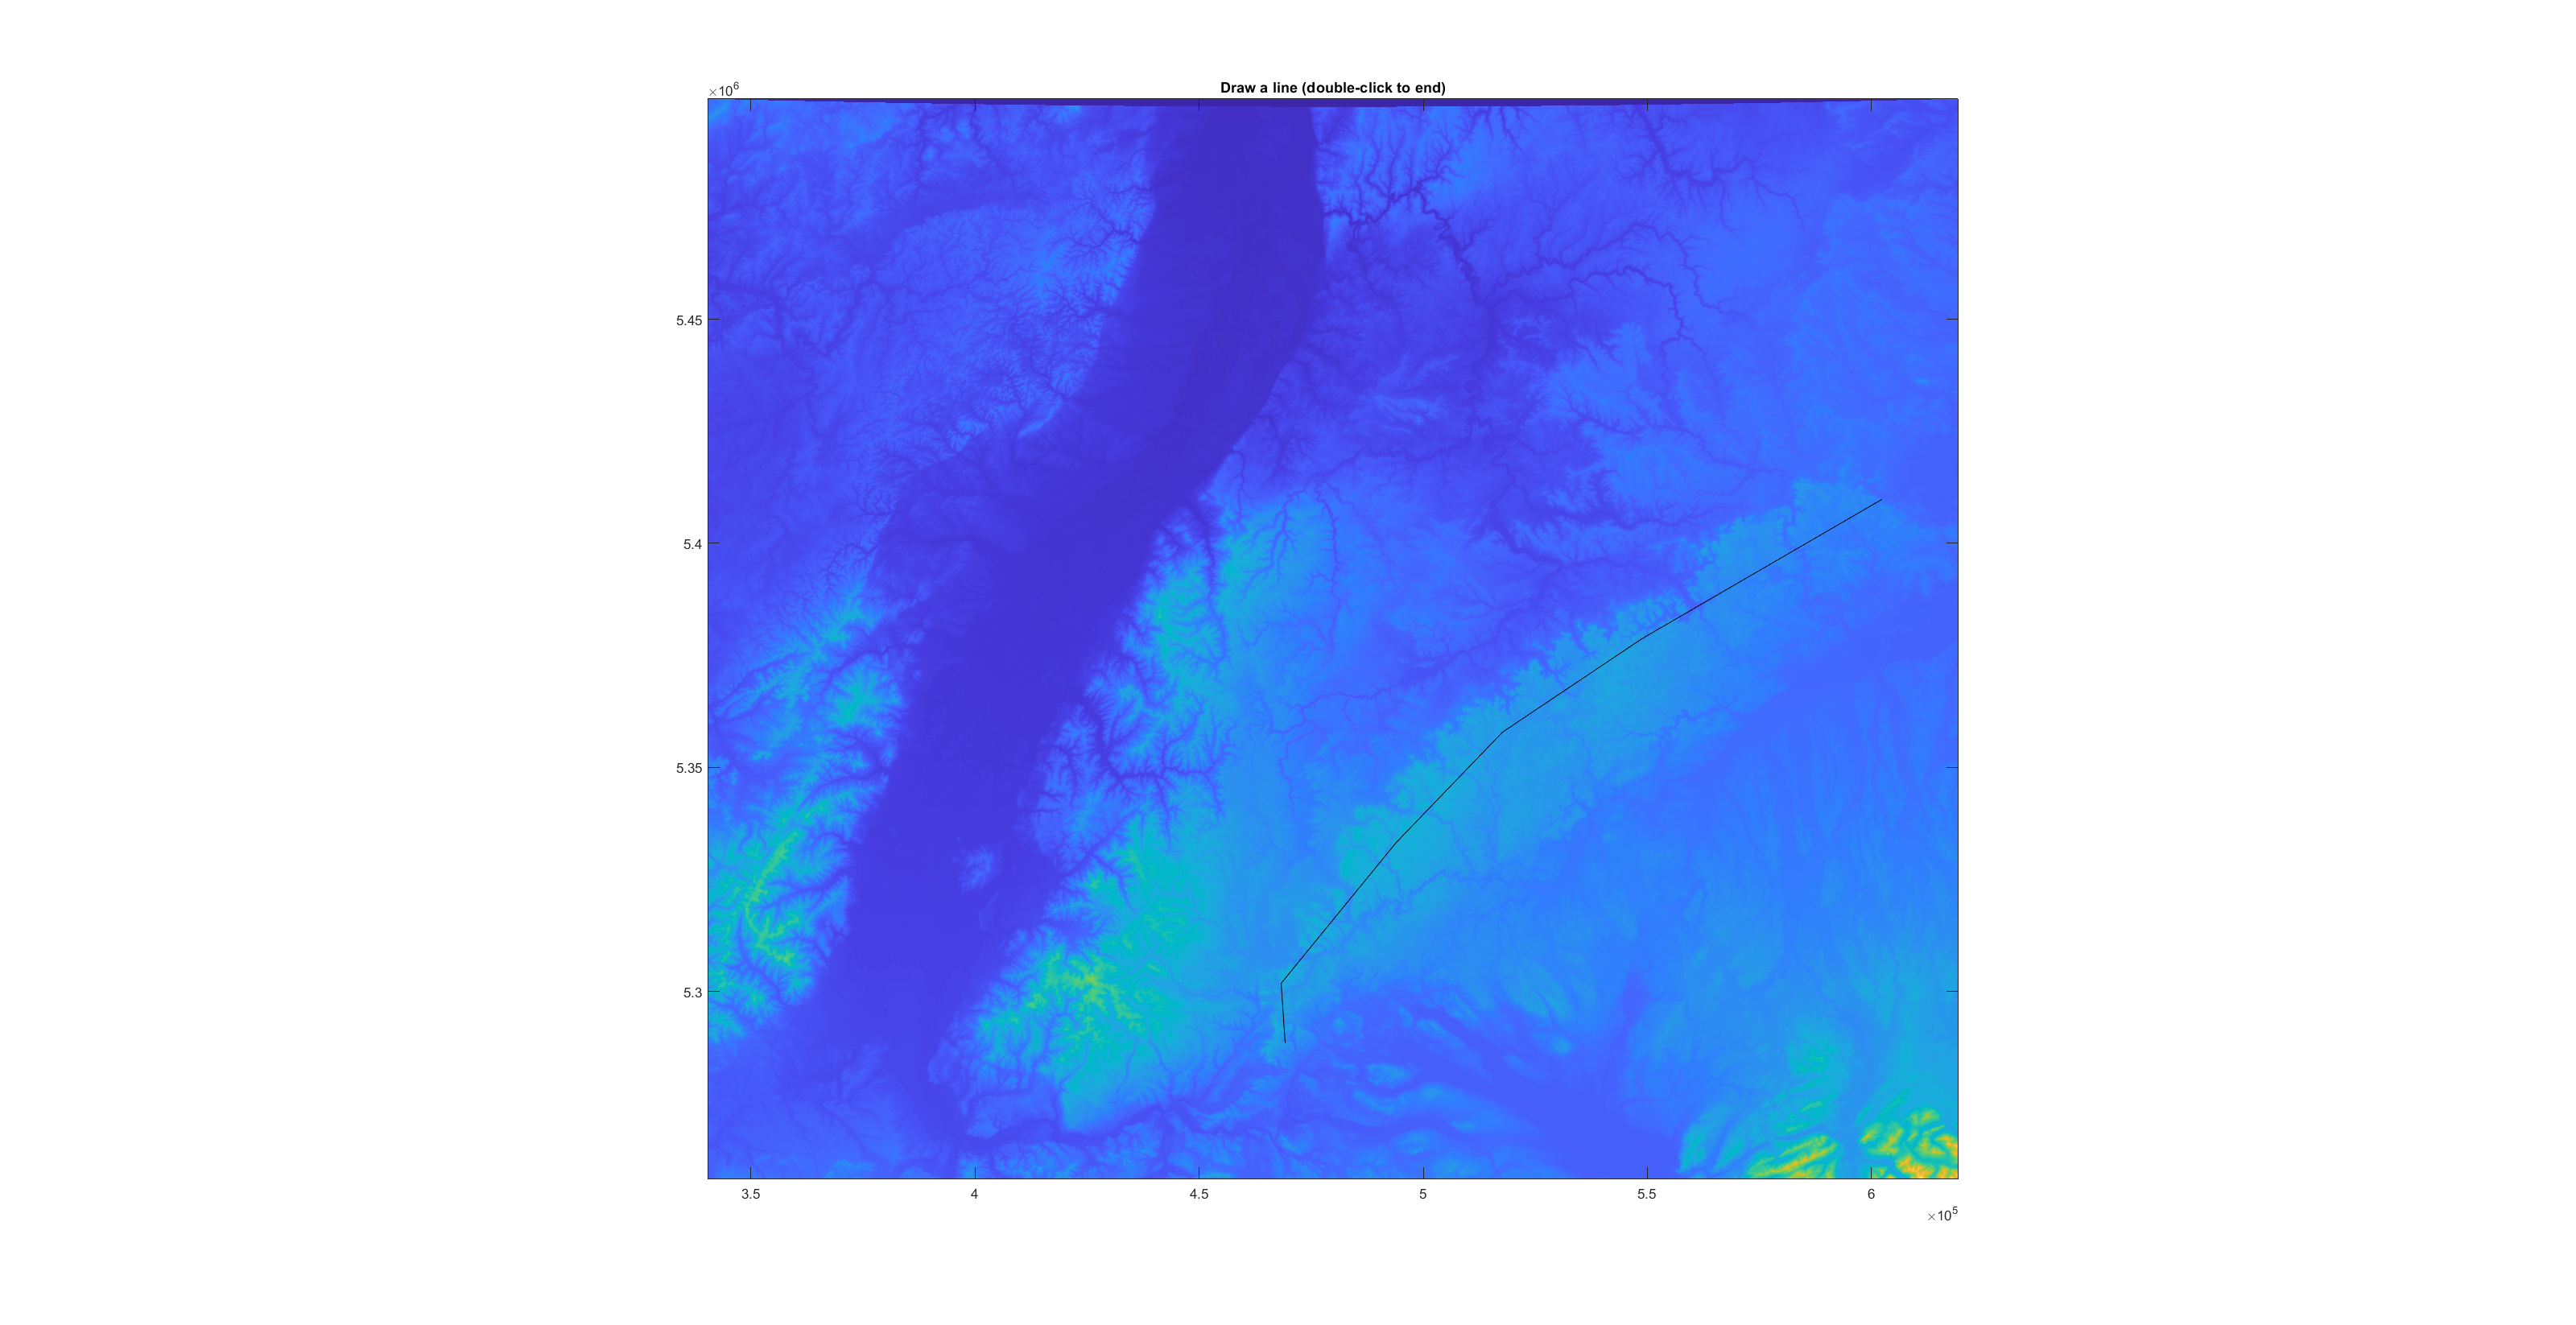

SW1 = SWATHobj(DEM,'width',10000);

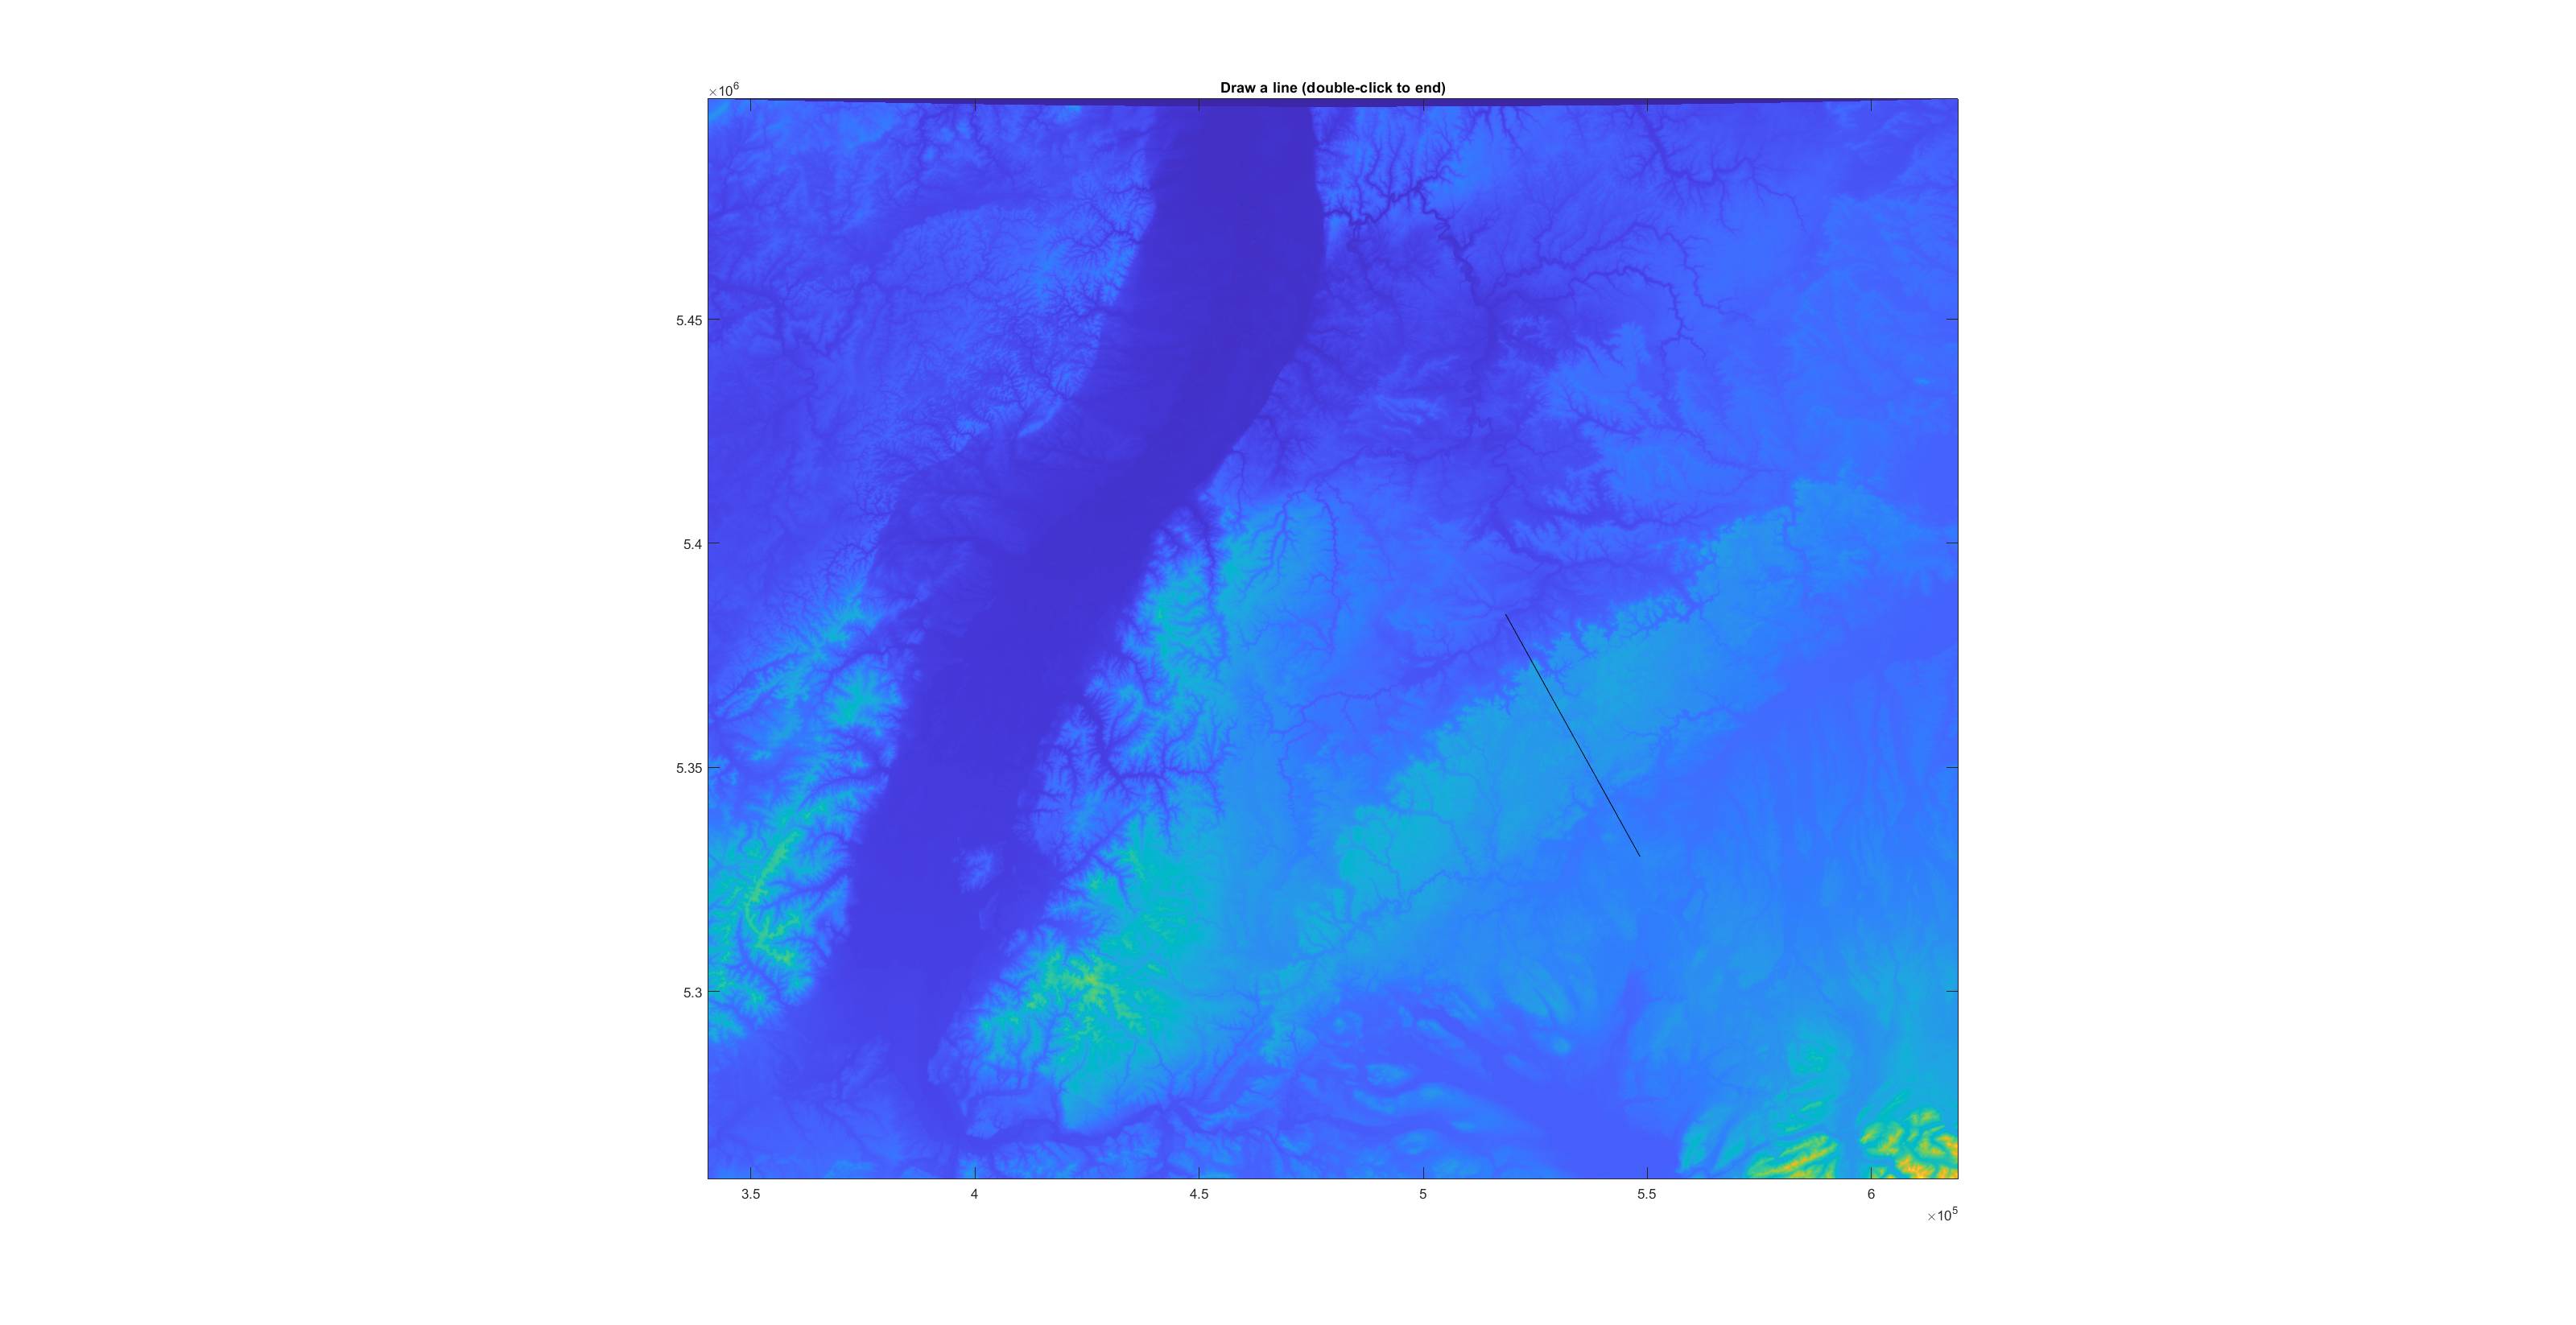

SW2 = SWATHobj(DEM,'width',50000);

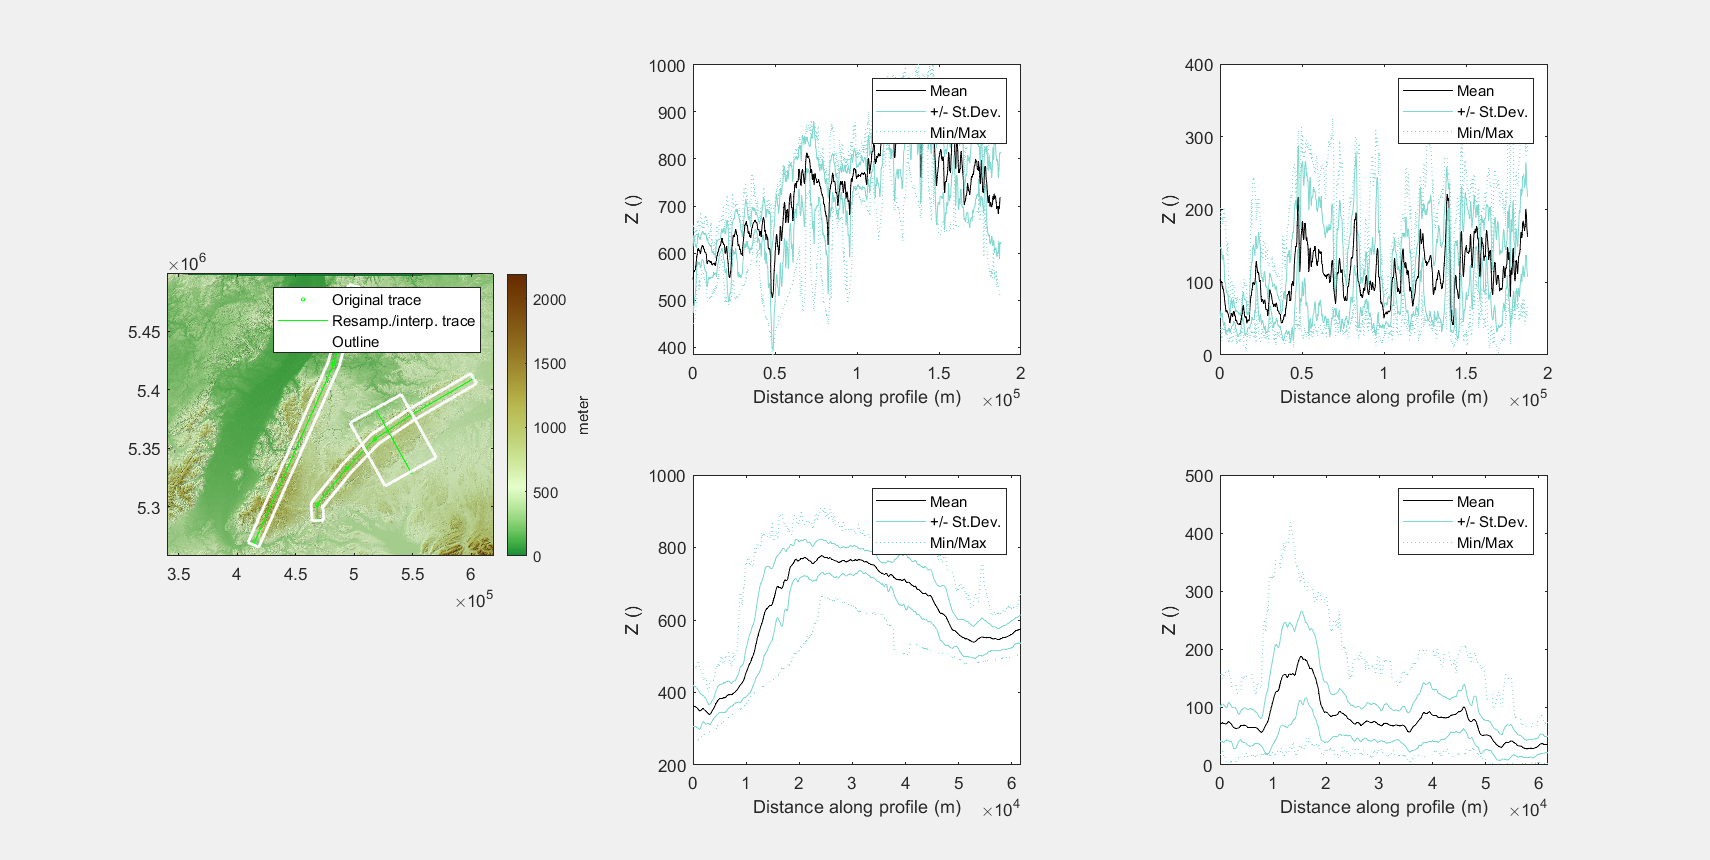

SWlocrel1 = mapswath(SW1,locrel);
SWlocrel2 = mapswath(SW2,locrel);

figure()
set(gcf,'Visible','on', 'units','normalized','outerposition',[0.05 0.05 0.90 0.90]) % this just makes sure the plot appears in a new large window for better visibility
tiledlayout(2,3)

% plot DEM and swath traces
ax1 = nexttile(1, [2, 1]); % [3, 1] means 3 rows and 1 column
axes(ax1);
imageschs(DEM,[],'colormap',landcolor,'colorbarylabel','meter');
hold on
plot(SW1)   
plot(SW2)

% plot swath 1
nexttile(2)
plotdz(SW1)   % elevation swath
xlabel('Distance along profile (m)')
% plot local relief swath 1
nexttile(3) 
plotdz(SWlocrel1) % elevation swath
xlabel('Distance along profile (m)')

% swath 2
nexttile(5)
plotdz(SW2) % elevation swath
xlabel('Distance along profile (m)')
nexttile(6)
plotdz(SWlocrel2) 
xlabel('Distance along profile (m)')